# Chess Clock

By: Andrew Nolan

### How to run program

All the code for Chess Clock is in a self-contained .mlx file. To run the code, open the file ChessClock.mlx in the MATLAB live editor and press run. 

Instructions on how to operate the Chess Clock can be found by clicking the "Help!" button once the app is running.

Alternatively, if ChessClock.mlx is in your Current Folder, you can run it by using either of the following commands in the Command Window:

>> run 'ChessClock.mlx'

>> ChessClock

#### Important Notes:

- Make sure to run the entire script from top to bottom to have the clock work correctly.

- Chess Clock relies on many timers existing in a certain order,*** make sure you do not have other MATLAB code running that will also be generating timers*** or the chess clock may not work.

- Chess Clock will cease to work in certain scenarios if more than one instance of it is running. ***Make sure to close all figures before relaunching the Chess Clock app***.

- Tested in MATLAB Online (in Chrome and Firefox) and Windows Desktop version R2021a.

#### Create the two clock faces

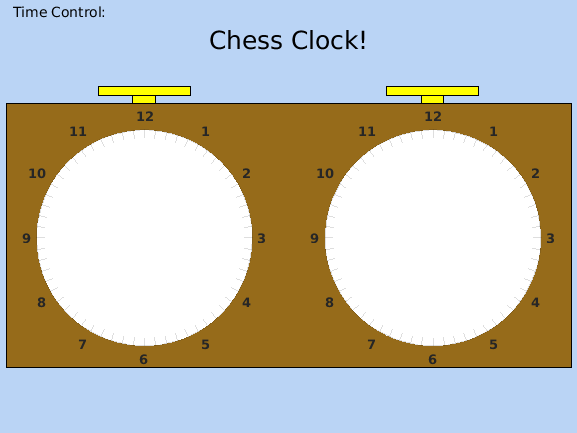

% Get a handle to the parent figure
parentFigure = figure();

% Set the figure properties for the title bar
parentFigure.MenuBar = 'None';
parentFigure.ToolBar = 'None';
parentFigure.Name = "Chess Clock";
parentFigure.NumberTitle = 'off';
parentFigure.Color = [0.73,0.83,0.96];

% Draw the clock box with graphics objects
backgroundAxes = axes('Parent', parentFigure);
backgroundAxes.XTick = [];
backgroundAxes.YTick = [];
backgroundAxes.Position = [0.01,0.15,0.98,0.61];

hold(backgroundAxes, "on");
% Make the clock box
clockBox = rectangle("Position",[0 0 1 0.5], "FaceColor",[0.59,0.42,0.10]);

% Draw the clock box "Buttons"
leftSmall = annotation("rectangle","Position", [0.23,0.76,0.039,0.02], "FaceColor","y");
leftRectangle = annotation("rectangle","Position", [0.17,0.78,0.16,0.02], "FaceColor","y");

rightSmall = annotation("rectangle","Position", [0.73,0.76,0.039,0.02], "FaceColor","y");
rightRectangle = annotation("rectangle","Position", [0.67,0.78,0.16,0.02], "FaceColor","y");

hold(backgroundAxes, "off");

% Draw the text
annotation("textbox","Position",[0 0.85 1 0.1],"String","Chess Clock!","LineStyle","none","FontSize",18,"HorizontalAlignment","center");
annotation("textbox","Position",[0.01 0.9 0.2 0.1],"String","Time Control: ","LineStyle","none");
delayText = annotation("textbox","Position",[0 -0.65 1 0.1],"String","5","LineStyle","none","FontSize",24,"HorizontalAlignment","center","Color","red", ...
    "FontWeight","bold");

% Create the left clock
leftClock = polaraxes();

% Set the properties of the Axes to make it look like a clock
leftClock.ThetaDir = "clockwise";
leftClock.ThetaZeroLocation = "top";
leftClock.ThetaTickLabel = [12 1:11];
leftClock.ThetaGrid = 0; 
leftClock.RTick = [];
leftClock.ThetaMinorTick = 0;
leftClock.ThetaTick = 0:6:360;
leftClock.ThetaTickLabel = ["12" strings(1,4) "1" strings(1,4) "2" strings(1,4) "3" strings(1,4) "4" strings(1,4) "5" strings(1,4) "6" strings(1,4) "7" strings(1,4) "8" strings(1,4) "9" strings(1,4) "10" strings(1,4) "11" strings(1,4)];
leftClock.TickLength = [0.04 0];
leftClock.FontWeight = 'bold';

% Position the clock on the left side of the window
leftClock.Units = "normalized"; % should be this by default, but just in case
leftClock.Position = [0 0.2 0.5 0.5];

% Create the right clock
rightClock = polaraxes();

% Set the properties of the Axes to make it look like a clock
rightClock.ThetaDir = "clockwise";
rightClock.ThetaZeroLocation = "top";
rightClock.ThetaTickLabel = [12 1:11];
rightClock.ThetaGrid = 0; 
rightClock.RTick = [];
rightClock.ThetaMinorTick = 0;
rightClock.ThetaTick = 0:6:360;
rightClock.ThetaTickLabel = ["12" strings(1,4) "1" strings(1,4) "2" strings(1,4) "3" strings(1,4) "4" strings(1,4) "5" strings(1,4) "6" strings(1,4) "7" strings(1,4) "8" strings(1,4) "9" strings(1,4) "10" strings(1,4) "11" strings(1,4)];
rightClock.TickLength = [0.04 0];
rightClock.FontWeight = 'bold';

% Position the clock on the right side of the window
rightClock.Units = "normalized"; % should be this by default, but just in case
rightClock.Position = [0.5 0.2 0.5 0.5];

#### Add the timer hands

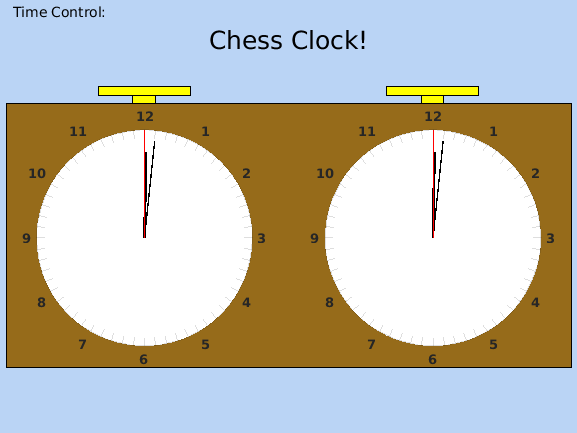

% Create a struct to hold time values
timeVals.hours = 0;
timeVals.minutes = 1;
timeVals.seconds = 0;
timeVals.delay = 5;

% Store the time vals in the parent figure's user data field
% This is important, because we need a handle so we can edit data in
% callback functions. 
% UI Controls callbacks can't return values and normal value variables
% can't be modified in a function due to scope. 
% This is my workaround, maybe I'll find something better later.
parentFigure.UserData = timeVals;

% Add the timer hands
hold(leftClock,"on")
leftHour = polarplot(leftClock,[0,0],[0,4],"k","LineWidth",2);
leftMinute = polarplot(leftClock,[0,2*pi/60],[0,4.5],"k","LineWidth",1);
leftSecond = polarplot(leftClock,[0,2*pi],[0,5],"r");
hold(leftClock,"off")

hold(rightClock,"on")
rightHour = polarplot(rightClock,[0,0],[0,4],"k","LineWidth",2);
rightMinute = polarplot(rightClock,[0,2*pi/60],[0,4.5],"k","LineWidth",1);
rightSecond = polarplot(rightClock,[0,2*pi],[0,5],"r");
hold(rightClock,"off")

% Set the initial positions
setTimerHands("1 Minute", leftHour, leftMinute, leftSecond, rightHour, rightMinute, rightSecond, parentFigure);

#### Add the interactive elements

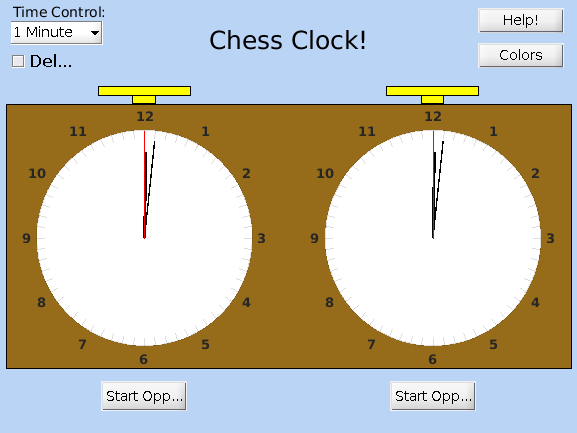

% Add the clock buttons to press
leftButton = uicontrol("Style", "pushbutton");
leftButton.String = "Start Opponent";
leftButton.Units = "normalized";
leftButton.Position = [0.176 0.05 0.15 0.07];

rightButton = uicontrol("Style","pushbutton");
rightButton.String = "Start Opponent";
rightButton.Units = "normalized";
rightButton.Position = [0.676 0.05 0.15 0.07];

% Add the help button
helpButton = uicontrol("Style","pushbutton");
helpButton.String = "Help!";
helpButton.Units = "normalized";
helpButton.Position = [0.83 0.92 0.15 0.06];


% Add the time control selector
timeSelector = uicontrol("Style","popupmenu");
timeSelector.String = ["1 Minute" "5 Minutes" "30 Minutes" "1 Hour" "Custom"];
timeSelector.Units = "normalized";
timeSelector.Position = [0.02 0.9 0.16 0.05];

% Add the delay checkbox
delaySelector = uicontrol("Style","checkbox");
delaySelector.String = "Delay?";
delaySelector.Units = "normalized";
delaySelector.Tooltip = "Enables or disables a delay for starting the clock";
delaySelector.BackgroundColor = [0.73,0.83,0.96];
delaySelector.FontSize = 12;
delaySelector.Position = [0.02,0.83,0.12,0.05];

% Make the color button
colorButton = uicontrol("Style","pushbutton");
colorButton.String = "Colors";
colorButton.Units = "normalized";
colorButton.Position = [0.83 0.84 0.15 0.06];

#### Make the timers move and set up callbacks

% Set up the two timers
leftTimer = timer;
leftTimer.ExecutionMode = "fixedRate";
leftTimer.Period = 1;

rightTimer = timer;
rightTimer.ExecutionMode = "fixedRate";
rightTimer.Period = 1;

% Add the button callbacks
leftTimer.TimerFcn = {@runTimer, leftSecond, leftMinute, leftHour,1,timeSelector, leftTimer, rightTimer, leftButton, rightButton, leftHour, leftMinute, leftSecond, rightHour, rightMinute, rightSecond, leftSmall, rightSmall, leftRectangle, rightRectangle, parentFigure, delayText};
rightTimer.TimerFcn = {@runTimer, rightSecond, rightMinute, rightHour,0,timeSelector, leftTimer, rightTimer, leftButton, rightButton, leftHour, leftMinute, leftSecond, rightHour, rightMinute, rightSecond, leftSmall, rightSmall, leftRectangle, rightRectangle, parentFigure, delayText};

leftButton.Callback = {@leftButtonPress, leftTimer, rightTimer, leftButton, rightButton, delaySelector, rightRectangle, leftRectangle, leftSmall, rightSmall, delayText, parentFigure};
rightButton.Callback = {@rightButtonPress, leftTimer, rightTimer, leftButton, rightButton, delaySelector, rightRectangle, leftRectangle, leftSmall, rightSmall, delayText, parentFigure};

timeSelector.Callback = {@chooseTime, timeSelector, leftTimer, rightTimer, leftButton, rightButton, leftHour, leftMinute, leftSecond, rightHour, rightMinute, rightSecond, leftSmall, rightSmall, leftRectangle, rightRectangle, parentFigure, delayText};

helpButton.Callback = @openHelpWindow;

colorButton.Callback = {@colorCustomizer, parentFigure, rightClock, leftClock, clockBox, rightSecond, leftSecond, delaySelector};

#### Stop and delete timers when everything is done

% Set up a callback to stop the timers when the figure is closed
parentFigure.DeleteFcn = {@cleanUpTimers, leftTimer, rightTimer};

#### Functions

function runTimer(~, ~, seconds, minutes, hours, lorr,timeSelector, leftTimer, rightTimer, leftButton, rightButton, leftHour, leftMinute, leftSecond, rightHour, rightMinute, rightSecond, leftSmall, rightSmall, leftRectangle, rightRectangle, parf, delayText)
    % Update the second hand
    secs = seconds.ThetaData(2) - 2*pi/60;
    seconds.ThetaData(2) = secs;
    
    % If a minute has passed update the hour and minute hand
    if round(secs, 4) == 0
        
        minutes.ThetaData(2) = minutes.ThetaData(2) - 2*pi/60;
        hours.ThetaData(2) = hours.ThetaData(2) - 2*pi/360;
        if round(seconds.ThetaData(2),2) == 0 && round(minutes.ThetaData(2),2) == 0 && round(hours.ThetaData(2),1) == 0
            % Display a message showing who won
            % lorr (left or right) is true if left clock is running
            if lorr
                warndlg("The left side has run out of time!","Out of time!");
            else
                warndlg("The right side has run out of time!","Out of time!");
            end
                       
            % Reset the clocks to the starting position
            chooseTime([], [],timeSelector, leftTimer, rightTimer, leftButton, rightButton, leftHour, leftMinute, leftSecond, rightHour, rightMinute, rightSecond, leftSmall, rightSmall, leftRectangle, rightRectangle, parf, delayText)
        else
            seconds.ThetaData(2) = 2*pi;
        end
    end    
end

% Clean up and delete timers once everything is done
function cleanUpTimers(~, ~, leftTimer, rightTimer)
    stop(leftTimer);
    stop(rightTimer);
    delete(leftTimer);
    delete(rightTimer);
    
    % Just in case something goes horribly wrong
    delete(timerfindall);
    
    % Thanks for playing!
    disp("Thanks for playing! :)");
end

% Stop the left timer and start the right timer
function leftButtonPress(~,~,leftTimer, rightTimer, leftButton, rightButton, delaySelector, leftRectangle, rightRectangle, leftSmall, rightSmall, delayText, parf)
    % Change the starting button text
    rightButton.String = "Hit Clock";
    leftButton.String = "Hit Clock";
    
    % Stop the left timer
    stop(leftTimer)
    
    % Change the button status
    leftButton.Enable = 'off';
    rightButton.Enable = 'on';
    
    % Adjust the button graphics
    leftRectangle.Position = [0.17,0.76,0.16,0.02];
    rightRectangle.Position = [0.67,0.78,0.16,0.02];
    leftSmall.Position = [-1 -1 -1 -1];
    rightSmall.Position =  [0.73,0.76,0.039,0.02];
    
    % start the right timer
    if(delaySelector.Value == 1)
        % Clear any old delay info
        timersToRemove = timerfindall();
        stop(timersToRemove(3:end));
        stop(timersToRemove(3:end));
        
        % Display the delay timer text
        delayText.Position = [0 0.65 1 0.1];
        delayText.String = parf.UserData.delay + 1;
        
        % Animate the delay
        delayCountdown = timer("ExecutionMode","fixedRate");
        delayCountdown.Period = 1;
        delayCountdown.TimerFcn = {@animateDelay, delayText};
        start(delayCountdown);
        
        % Start the opponent's clock after a delay
        delayTimer = timer('StartDelay', parf.UserData.delay);
        delayTimer.TimerFcn = {@handleDelay, leftTimer, rightTimer, delayTimer, delayCountdown, delayText};
        start(delayTimer);
        
    else
        rightTimer.start();
    end

end

% Stop the right timer and start the left timer
function rightButtonPress(~,~,leftTimer, rightTimer, leftButton, rightButton, delaySelector, leftRectangle, rightRectangle, leftSmall, rightSmall, delayText, parf)
    % Change the starting button text
    rightButton.String = "Hit Clock";
    leftButton.String = "Hit Clock";

    % Stop the right timer
    stop(rightTimer);
    
    % Change the button status
    leftButton.Enable = 'on';
    rightButton.Enable = 'off';
    
     % Adjust the button graphics
    leftRectangle.Position = [0.17,0.78,0.16,0.02];
    rightRectangle.Position = [0.67,0.76,0.16,0.02];
    leftSmall.Position = [0.23,0.76,0.039,0.02];
    rightSmall.Position =  [-1 -1 -1 -1];
    
    % start the left timer
    if(delaySelector.Value == 1)
        % Clear any old delay info
        timersToRemove = timerfindall();
        stop(timersToRemove(3:end));
        stop(timersToRemove(3:end));
        
        % Display the delay timer text
        delayText.Position = [0 0.65 1 0.1];
        delayText.String = parf.UserData.delay + 1;
        
        % Animate the delay
        delayCountdown = timer("ExecutionMode","fixedRate");
        delayCountdown.Period = 1;
        delayCountdown.TimerFcn = {@animateDelay, delayText};
        start(delayCountdown);
        
        % Start the opponent's clock after a delay
        delayTimer = timer('StartDelay',parf.UserData.delay);
        delayTimer.TimerFcn = {@handleDelay, rightTimer, leftTimer, delayTimer, delayCountdown, delayText};
        start(delayTimer);
        
    else
        leftTimer.start();
    end
end

% Animate the delay countdown text
function animateDelay(~, ~, delayText)
    delayNum = str2double(delayText.String) - 1;
    if delayNum == 0
        delayText.Position = [0 -0.65 1 0.1];
    end
    delayText.String = delayNum;
end

% Handle the delay timer
function handleDelay(~, ~, stopTimer, startTimer, delayTimer, delayCountdown, delayText)
    delayText.Position = [0 -0.65 1 0.1];
    stop(stopTimer);
    startTimer.start();
    stop(delayTimer);
    stop(delayCountdown);
    delete(delayTimer);
    delete(delayCountdown);
end

% Set the timer hands to certain starting positions based on the time control
function setTimerHands(timeControl, leftHour, leftMinute, leftSecond, rightHour, rightMinute, rightSecond, parf)
    switch timeControl
        case "1 Minute"
            leftHour.ThetaData(2) = 2*pi/360;
            leftMinute.ThetaData(2) = 2*pi/60;
            leftSecond.ThetaData(2) = 2*pi;
            
            rightHour.ThetaData(2) = 2*pi/360;
            rightMinute.ThetaData(2) = 2*pi/60;
            rightSecond.ThetaData(2) = 2*pi;
            
            parf.UserData.hours = 0;
            parf.UserData.minutes = 1;
            parf.UserData.seconds = 0;
        case "5 Minutes"
            leftHour.ThetaData(2) = 2*pi/72;
            leftMinute.ThetaData(2) = pi/6;
            leftSecond.ThetaData(2) = 2*pi;
            
            rightHour.ThetaData(2) = 2*pi/72;
            rightMinute.ThetaData(2) = pi/6;
            rightSecond.ThetaData(2) = 2*pi;
            
            parf.UserData.hours = 0;
            parf.UserData.minutes = 5;
            parf.UserData.seconds = 0;
        case "30 Minutes"
            leftHour.ThetaData(2) = pi/12;
            leftMinute.ThetaData(2) = pi;
            leftSecond.ThetaData(2) = 2*pi;
            
            rightHour.ThetaData(2) = pi/12;
            rightMinute.ThetaData(2) = pi;
            rightSecond.ThetaData(2) = 2*pi;
            
            parf.UserData.hours = 0;
            parf.UserData.minutes = 30;
            parf.UserData.seconds = 0;
        case "1 Hour"
            leftHour.ThetaData(2) = pi/6;
            leftMinute.ThetaData(2) = 2*pi;
            leftSecond.ThetaData(2) = 2*pi;
            
            rightHour.ThetaData(2) = pi/6;
            rightMinute.ThetaData(2) = 2*pi;
            rightSecond.ThetaData(2) = 2*pi;
            
            parf.UserData.hours = 1;
            parf.UserData.minutes = 0;
            parf.UserData.seconds = 0;
        case "Custom"
            % Get the custom settings from user input
            results = handleCustomTimePopup(parf.UserData);
            
            if isempty(results)
                % Set the clock hands to the previous settings if custom is cancelled
                leftMinute.ThetaData(2) = 2*pi/60*parf.UserData.minutes;
                leftHour.ThetaData(2) = 2*pi/12*parf.UserData.hours + pi/360*parf.UserData.minutes;
                leftSecond.ThetaData(2) = 2*pi/60*parf.UserData.seconds;
                
                rightMinute.ThetaData(2) = 2*pi/60*parf.UserData.minutes;
                rightHour.ThetaData(2) = 2*pi/12*parf.UserData.hours + pi/360*parf.UserData.minutes;
                rightSecond.ThetaData(2) = 2*pi/60*parf.UserData.seconds;
            else
                seconds = round(str2double(results{3}));
                mins = round(str2double(results{2}));
                hours = round(str2double(results{1}));
                delay = round(str2double(results{4}));
                
                % Make sure only numbers are input
                if isnan(seconds)
                    seconds = 0;
                end
                
                if isnan(mins)
                    mins = 0;
                end
                
                if isnan(hours)
                    hours = 0;
                end
                
                if isnan(delay)
                    delay = 0;
                end
                
                % Update the time data 
                parf.UserData.hours = hours;
                parf.UserData.minutes = mins;
                parf.UserData.seconds = seconds;
                
                % Make sure there are no silly values
                mins = mins + hours * 60;
                if mins < 1
                    mins = 1;
                end
                
                if seconds == 0
                    seconds = 60;
                elseif seconds < 1
                    seconds = 1;
                end
                
                if delay < 0
                    delay = 0;
                end
                
                % Set the delay
                parf.UserData.delay = delay;
                
                % Set the clock hands
                leftMinute.ThetaData(2) = 2*pi/60*mins;
                leftHour.ThetaData(2) = 2*pi/12*hours + pi/360*(mod(mins, 60));
                leftSecond.ThetaData(2) = 2*pi/60*seconds;
                
                rightMinute.ThetaData(2) = 2*pi/60*mins;
                rightHour.ThetaData(2) = 2*pi/12*hours + pi/360*(mod(mins, 60));
                rightSecond.ThetaData(2) = 2*pi/60*seconds;
            end 
    end
end

% Open the custom time control options
function results = handleCustomTimePopup(timeVals)
    options = ["Hours" "Minutes" "Seconds" "Delay"];
    inputTitle = "Custom Time Control";
    defaultValues = {num2str(timeVals.hours), num2str(timeVals.minutes), num2str(timeVals.seconds), num2str(timeVals.delay)};
    results = inputdlg(options, inputTitle, [1 30], defaultValues);
end

% Choose the time control via dropdown
function chooseTime(~, ~,timeSelector, leftTimer, rightTimer, leftButton, rightButton, leftHour, leftMinute, leftSecond, rightHour, rightMinute, rightSecond, leftSmall, rightSmall, leftRectangle, rightRectangle, parf, delayText)
    % Stop the timers
    stop(leftTimer);
    stop(rightTimer);
    stop(timerfindall);
    delayText.Position = [0 -0.65 1 0.1];
    
    
    % Reset the buttons
    rightButton.String = "Start Opponent";
    leftButton.String = "Start Opponent";
    leftButton.Enable = 'on';
    rightButton.Enable = 'on';
    
    % Reset the clock "button" rectangles
    leftRectangle.Position = [0.17,0.78,0.16,0.02];
    rightRectangle.Position = [0.67,0.78,0.16,0.02];
    leftSmall.Position = [0.23,0.76,0.039,0.02];
    rightSmall.Position =  [0.73,0.76,0.039,0.02];
    
    % Change the time control to the new value
    val = timeSelector.Value;
    str = timeSelector.String;
    setTimerHands(str{val}, leftHour, leftMinute, leftSecond, rightHour, rightMinute, rightSecond, parf);
end

% Open the help window
function openHelpWindow(~,~)
    helpdlg("Welcome to chess clock!" + newline + newline + ...
        "This is a basic chess clock app. Choose a time control from the drop down menu and decide if you want a delay or not. Then press a button to start your opponent's clock. After you move, you can hit your clock to stop your time and start your opponents. The app will inform you if a player runs out of time." + newline + newline +...
        "Modify the time control at any time to restart the timers." + newline + newline + ...
        "Have fun!","Chess Clock Info");
end

% Handle the UI Color Customization
function colorCustomizer(~,~, parentFigure, clockFaceRight, clockFaceLeft, clockBox, secondHandRight, secondHandLeft, delaySelector)
    d = dialog('Name','Customize Colors!');
    d.Position(3) = 250;
    d.Position(4) = 150;

    % Add text and buttons
    uicontrol('Parent',d,'Style','text','HorizontalAlignment','left','Units','normalized','Position',[0.02 0.88 0.65 0.1],'String','Change the background color:');
    
    uicontrol('Parent',d,'Units','normalized','Position',[0.73 0.88 0.25 0.1],'String','Change','Callback',{@openColorPicker, parentFigure,delaySelector});
    
    uicontrol('Parent',d,'Style','text','HorizontalAlignment','left','Units','normalized','Position',[0.02 0.75 0.65 0.1],'String','Change the clock face color:');
    
    uicontrol('Parent',d,'Units','normalized','Position',[0.73 0.75 0.25 0.1],'String','Change','Callback',{@openColorPicker, clockFaceRight, clockFaceLeft});
    
    uicontrol('Parent',d,'Style','text','HorizontalAlignment','left','Units','normalized','Position',[0.02 0.62 0.65 0.1],'String','Change the clock box color:');
    
    uicontrol('Parent',d,'Units','normalized','Position',[0.73 0.62 0.25 0.1],'String','Change','Callback',{@openColorPicker, clockBox,[]});
    
    uicontrol('Parent',d,'Style','text','HorizontalAlignment','left','Units','normalized','Position',[0.02 0.49 0.67 0.1],'String','Change the second hand color:');
    
    uicontrol('Parent',d,'Units','normalized','Position',[0.73 0.49 0.25 0.1],'String','Change','Callback',{@openColorPicker, secondHandRight, secondHandLeft});
    
    % Add a button to close the window
    uicontrol('Parent',d,'Position',[85 20 70 25],'String','Done','Callback','delete(gcf)');
end

% Pick a color and set the appropriate graphics elements' properties
function openColorPicker(~, ~, graphicsHandle, optionalGraphicsHandle)
    if class(graphicsHandle) == "matlab.graphics.primitive.Rectangle"
        graphicsHandle.FaceColor = uisetcolor(graphicsHandle);
    else
        graphicsHandle.Color = uisetcolor(graphicsHandle);
    end
    if class(optionalGraphicsHandle) == "matlab.ui.control.UIControl"
        optionalGraphicsHandle.BackgroundColor = graphicsHandle.Color;
    elseif ~isempty(optionalGraphicsHandle)
        optionalGraphicsHandle.Color = graphicsHandle.Color;
    end
end